# 10/3

load('7.23.25_Pos1_WORKINGSET.mat',"disps","downs","ups","pivots","tracks");
tic
[pivots,xmins]=Pivots(tracks,disps,'distance',5);
toc

Elapsed time is 0.100960 seconds.


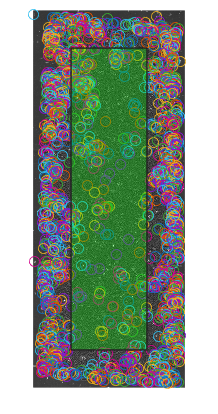


% take a look at spatial distribution of tracks that do not turn/
%reach xmin before stimswitch
figure
earlies=find(xmins<33);
im=imread("E:\CohenLab\7.23.25_CORGI_UTURN\Pos1\pos1_ROTTempMCROP8bit\pos1_09.tif");
imshow(im)
hold on
for i=earlies
    scatter(tracks{i,1}(1,2),tracks{i,1}(1,3))
    
end
%looks like they are almost all edge cells, which I probably want
%to exclude from this analysis for now anyway.

%plot a scaled down rectangle to check bulk cropping bounds:
prop1=0.5;
prop2=0.2;
x1=(size(im,2)*prop1)/2;
x2=size(im,2)-x1;
y1=(size(im,1)*prop2)/2;
y2=size(im,1)-y1;
x=[x1 x1 x2 x2];
y=[y2 y1 y1  y2];
patch(x,y,'green','FaceAlpha',0.3)

hold off; % Release the plot hold

%crop data to the bulk
BulkTracks={};
BulkDisps={};
BulkUps=[];
BulkDowns=[];
prop1=0.5;
prop2=0.2;
x1=(size(im,2)*prop1)/2;   x2=size(im,2)-x1;
y1=(size(im,1)*prop2)/2;  y2=size(im,1)-y1;
for i=1:length(tracks)
    if tracks{i,1}(1,2:3)<[x2 y2] & tracks{i,1}(1,2:3)>[x1 y1]
        BulkTracks{end+1,1}=tracks{i}; % Store the current track in BulkTracks
        BulkDisps{end+1,1}=disps{i};
        if ismember(i,ups)
            BulkUps(end+1)=i;
        elseif ismember(i,downs)
            BulkDowns(end+1)=i;
        end
    end
end

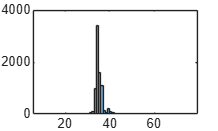

%check if cropping reduces the amount of early xmin cells
[pivots,xmins]=Pivots(BulkTracks,BulkDisps,'distance',5);
figure 
histogram(xmins)


test=length(find(xmins<33));
test/length(BulkDisps)

ans = 0.0323

%about 3.23% of cells still turn early (264). Probably ok.


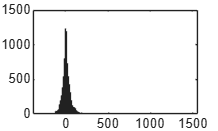

%OK now I want to look at the distribution of AUCs. How many turns are wide
%vs pretty narrow?

%alter UDclasser to output AUC lists in order of track index (not label ID)

[ups,downs,dcurve]=UDclasser(pivots,1:length(pivots),0);

figure
histogram(dcurve)

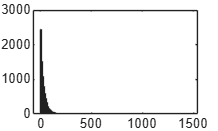

figure
histogram(abs(dcurve))

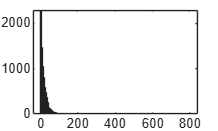

%scale dcurve to microns
dcurve=dcurve*0.7364^2;
figure
histogram(abs(dcurve))

%sort by largest to smallest MAGNITUDE to take a look...
[dclist,list]=sort(abs(dcurve));



%where are the widest turns?

figure
widest=list(1:1000);
im=imread("E:\CohenLab\7.23.25_CORGI_UTURN\Pos1\pos1_ROTTempMCROP8bit\pos1_09.tif");
imshow(im)
hold on
for i=widest'
    scatter(BulkTracks{i,1}(1,2),BulkTracks{i,1}(1,3),'r')
    
end


%figure
narrowest=list(end-1000:end);

narrowest =         3816        8009        7320        7595        6965        6813        5525        7802        1267        8029        4152         492        2399        7041        1694        3060          88        7685        1946        5673        4831         810        4864        2528        6258        6724        2343        4175        7370        3312        4817        5897        4553        2233        6257        6560        3534        2892        4009        6634        7584        5909        2135        5458        8005        7258          44         754        4132        5461


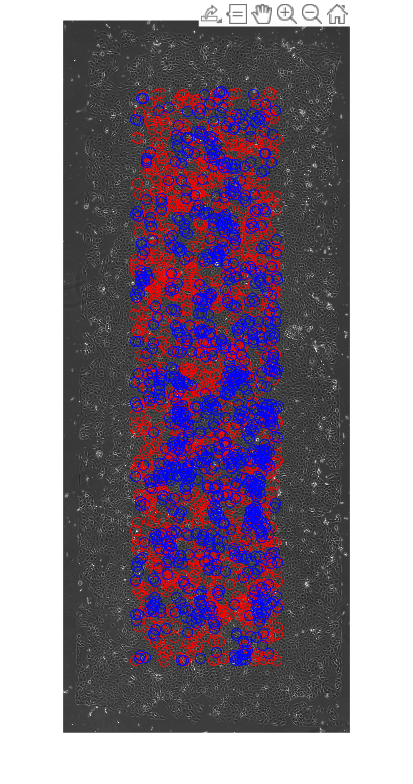

%im=imread("E:\CohenLab\7.23.25_CORGI_UTURN\Pos1\pos1_ROTTempMCROP8bit\pos1_09.tif");
%imshow(im)
hold on
for i=narrowest
    scatter(BulkTracks{i,1}(1,2),BulkTracks{i,1}(1,3),'b')
    
end


%seems like there is some clustering here. How does it compare to u/d
%clustering?

fig =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [383 189 560 337.2662]
       Units: 'pixels'

  Show all properties


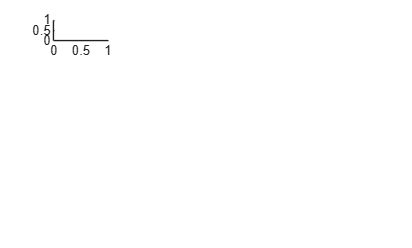

Error using surf (line 71)
Data dimensions must agree.

Error in TilePlot (line 50)
        surf([x(:) x(:)], [y(:) y(:)], [z(:) z(:)], ...  % Reshape and replicate data
        ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

%I want to have a look at some of the "widest" and "narrowest" turns to see
%how this dcurve metric is doing intuitively
TilePlot('N',0,list(end-24:end),tracks,disps)